# Problem Set 3

Michael Chan

Monte Carlo and the Second Derivative of the Log-likelihood Function

1) set the random number generator seed to zero

2) draw 5 values from the Bernoulli Distribution with $p = 0.25$

rng(0);
x = rand([5 1]);

%making our observations 0 if over .25 and 1 otherwise.
for i = 1:length(x)
    if x(i,1) > .25
        x(i,1) = 0;
    else
        x(i,1) = 1;
    end
end



Estimating $p$ from this data. 

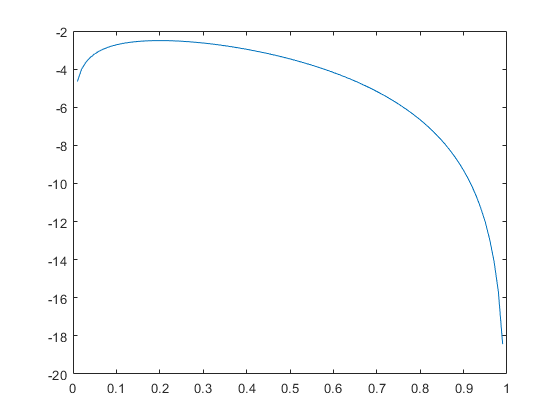


p = .01:.01:1;

like = zeros(length(p),1);
loglike1 = zeros(length(p),1);
for k = 1:length(p)
    like_i = log(binopdf(x,1,p(k)));
    loglike1(k) = sum(like_i);

end

plot(p,loglike1)


%plot(p,log(like))
[max_val,max_index] = max(loglike1)

max_val = -2.5020

max_index = 20

With a sample size of 5, we get an estimate of .2 which we might notice as the mean of our sample.

mean(x)

ans = 0.2000

4) Reset the random number generator seed

rng('default')

5) Take 500 draws and make a plot of this log likelihood function over possible values of $p\in \left(0,1\right)$

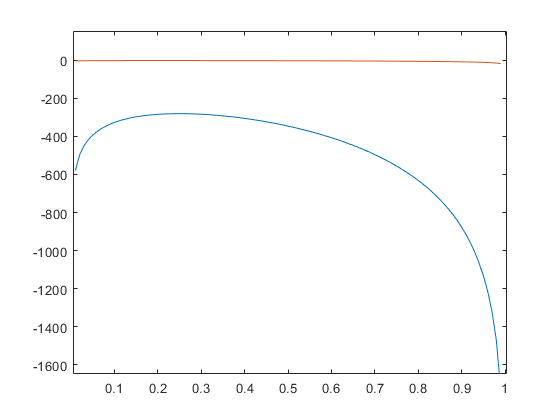

x = rand([500 1]);

for i = 1:length(x)
    if x(i,1) > .25
        x(i,1) = 0;
    else
        x(i,1) = 1;
    end
end

p_vals = .01:.01:1;

loglike2 = zeros(length(p_vals),1);
for k = 1:length(p_vals)
    like_i = log(binopdf(x,1,p_vals(k)));
    loglike2(k) = sum(like_i);
    

end

plot(p_vals,loglike2)
hold on
plot(p,loglike1)

Here we have both our plots with the orange line being the small sample and blue being our larger sample.

[max_val,max_index] = max(loglike2)

max_val = -281.1676

max_index = 25

mean(x)

ans = 0.2500

With more observations we have a more accurate result from our maximum likelihood estimation.

Question:

Use these two plots to explain why the second experiment (the one with more data) results in a log-likelihood function that is more precise.

       At a glance, it is better to use the larger sample estimator since the maximum is much more obvious on the larger sample estimator rather than the five observation sample's estimator.

Specifically, the precision of the maximum likelihood estimator is related to the second derivative of the log-likelihood function.  

      The second derivative from what I understand is a measure of the rate of change of how something is changing. We can see that the second estimator has a greater curvature to it and we can visually see that the change in the rate at which the function is changing is greater than the first estimator.

Using these experiments, explain why this relationship makes sense, i.e., a very smaller second derivative makes the shape of the log-likelihood more **flat**, which makes the estimator **less** precise.  

The log-likelihood with more data should have a more precise estimator, which can be seen because the shape of the log-likelihood is more **curved** which implies that the second derivative is **greater than the sample with less observations.**